% ECE435-Medical Imaging
% Professor Brian Frost-Laplante
% Project 1 - Imaging Fundamentals
clc; clear; close all


## I. Slicing

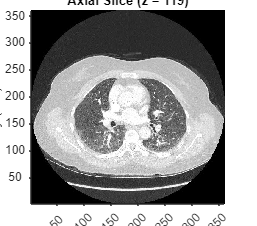

% DICOM attributes
pixelSpacing = 0.703; % mm (for both x and y)
sliceSpacing = 0.625; % mm (spacing in z)

stack_dir = 'thoraxCT';
files = dir(fullfile(stack_dir, '*.jpg'));
num_slices = length(files);

% Read the first image to determine the image size and class
sample = rgb2gray(imread(fullfile(stack_dir, files(1).name)));
[x_dim, y_dim] = size(sample);
img_class = class(sample);

% Pre-allocate the 3D volume array
volume = zeros(x_dim, y_dim, num_slices, img_class);

% Read each image and store in the volume
for i = 1:num_slices
    img = rgb2gray(imread(fullfile(stack_dir, files(i).name)));
    volume(:,:,i) = img;
end

% Middle indices
mid_x = round(x_dim/2);
mid_y = round(y_dim/2);
mid_z = round(num_slices/2);

% Display slices near the middle of subject
figure, axial_slice = display_slice('Axial', mid_z, volume, pixelSpacing, sliceSpacing, x_dim, y_dim, gca);

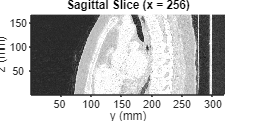

figure, sagittal_slice = display_slice('Sagittal', mid_x, volume, pixelSpacing, sliceSpacing, y_dim, num_slices, gca);

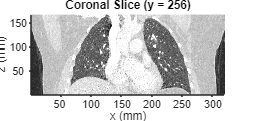

figure, coronal_slice = display_slice('Coronal', mid_y, volume, pixelSpacing, sliceSpacing, x_dim, num_slices, gca);

## II. Salt and Pepper

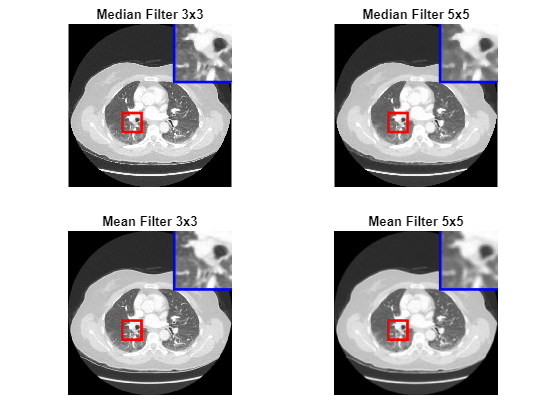

function noisy_img = add_seasoning(img, p) % Season with salt and pepper
    % p must be less than 0.5
    noisy_img = img;
    r = rand(size(img));
    noisy_img(r < p) = 255; % Salt
    noisy_img(r > 1 - p) = 0; % Pepper
end

% Use Axial Slice for salt and pepper analysis
img = axial_slice;

% Magnification parameters
roi_x = 170;
roi_y = 280;
roi_w = 60;
roi_h = 60;
roi = [roi_x, roi_y, roi_w, roi_h]; 
magnification_factor = 3;
overlay_x = x_dim - roi_w * magnification_factor;
overlay_y = 0;
overlay_position = [overlay_x, overlay_y];

% Apply median and mean filters with 3x3 and 5x5 neighborhoods
median_3x3 = medfilt2(img, [3 3]); % Matlab median filter
median_5x5 = medfilt2(img, [5 5]);
mean_3x3 = filter2(fspecial('average', 3), img); % Matlab 2D filter
mean_5x5 = filter2(fspecial('average', 5), img);

% Display the filtered images
figure, tiledlayout(2,2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile, display_magnified_roi(median_3x3, roi, magnification_factor, overlay_position, gca), title('Median Filter 3x3');
nexttile, display_magnified_roi(median_5x5, roi, magnification_factor, overlay_position, gca), title('Median Filter 5x5');
nexttile, display_magnified_roi(mean_3x3, roi, magnification_factor, overlay_position, gca), title('Mean Filter 3x3');
nexttile, display_magnified_roi(mean_5x5, roi, magnification_factor, overlay_position, gca), title('Mean Filter 5x5');
print('Median and Mean', '-dsvg')

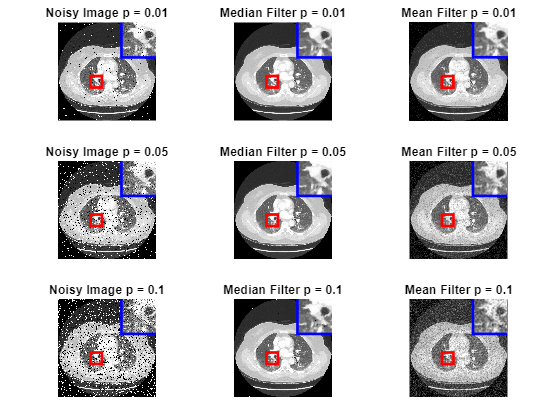


% Generate noisy images
seasoned_img_01 = add_seasoning(img, 0.01);
seasoned_img_05 = add_seasoning(img, 0.05);
seasoned_img_10 = add_seasoning(img, 0.1);

% Apply 3x3 median and mean filters
median_3x3_seasoned_01 = medfilt2(seasoned_img_01, [3 3]);
mean_3x3_seasoned_01 = filter2(fspecial('average', 3), seasoned_img_01);

median_3x3_seasoned_05 = medfilt2(seasoned_img_05, [3 3]);
mean_3x3_seasoned_05 = filter2(fspecial('average', 3), seasoned_img_05);

median_3x3_seasoned_10 = medfilt2(seasoned_img_10, [3 3]);
mean_3x3_seasoned_10 = filter2(fspecial('average', 3), seasoned_img_10);

% Display noise, median and mean images for each noise probability 
% (9 images total)
figure, tiledlayout(3,3, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile, display_magnified_roi(seasoned_img_01, roi, magnification_factor, overlay_position, gca), title('Noisy Image p = 0.01');
nexttile, display_magnified_roi(median_3x3_seasoned_01, roi, magnification_factor, overlay_position, gca), title('Median Filter p = 0.01');
nexttile, display_magnified_roi(mean_3x3_seasoned_01, roi, magnification_factor, overlay_position, gca), title('Mean Filter p = 0.01');

nexttile, display_magnified_roi(seasoned_img_05, roi, magnification_factor, overlay_position, gca), title('Noisy Image p = 0.05');
nexttile, display_magnified_roi(median_3x3_seasoned_05, roi, magnification_factor, overlay_position, gca), title('Median Filter p = 0.05');
nexttile, display_magnified_roi(mean_3x3_seasoned_05, roi, magnification_factor, overlay_position, gca), title('Mean Filter p = 0.05');

nexttile, display_magnified_roi(seasoned_img_10, roi, magnification_factor, overlay_position, gca), title('Noisy Image p = 0.1');
nexttile, display_magnified_roi(median_3x3_seasoned_10, roi, magnification_factor, overlay_position, gca), title('Median Filter p = 0.1');
nexttile, display_magnified_roi(mean_3x3_seasoned_10, roi, magnification_factor, overlay_position, gca), title('Mean Filter p = 0.1');
print('Seasoned', '-dsvg')

## III. Gauss' Wrath

### Gaussian Noise

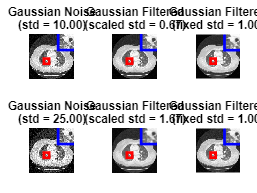

noise_stds = [10, 25];
filt_stds = noise_stds./ 15; % Arbitrary scaling
fixed_filt_std = 1;
% Function to add Gaussian white noise
add_gauss_noise = @(img, noise_std) imnoise(img, 'gaussian', 0, (noise_std / 255)^2);

gauss_noise_img_1 = add_gauss_noise(img, noise_stds(1));
gauss_noise_img_2 = add_gauss_noise(img, noise_stds(2));
gauss_filt_scaled_img_1 = imgaussfilt(gauss_noise_img_1, filt_stds(1));
gauss_filt_scaled_img_2 = imgaussfilt(gauss_noise_img_2, filt_stds(2));
gauss_filt_fixed_img_1 = imgaussfilt(gauss_noise_img_1, fixed_filt_std);
gauss_filt_fixed_img_2 = imgaussfilt(gauss_noise_img_2, fixed_filt_std);

figure, tiledlayout(2,3, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile, display_magnified_roi(gauss_noise_img_1,roi, magnification_factor, overlay_position, gca), title({"Gaussian Noise", sprintf("(std = %.2f)", noise_stds(1))});
nexttile, display_magnified_roi(gauss_filt_scaled_img_1, roi, magnification_factor, overlay_position, gca), title({"Gaussian Filtered", sprintf("(scaled std = %.2f)", filt_stds(1))});
nexttile, display_magnified_roi(gauss_filt_fixed_img_1, roi, magnification_factor, overlay_position, gca), title({"Gaussian Filtered", sprintf("(fixed std = %.2f)", fixed_filt_std)});

nexttile, display_magnified_roi(gauss_noise_img_2,roi, magnification_factor, overlay_position, gca), title({"Gaussian Noise", sprintf("(std = %.2f)", noise_stds(2))});
nexttile, display_magnified_roi(gauss_filt_scaled_img_2, roi, magnification_factor, overlay_position, gca), title({"Gaussian Filtered", sprintf("(scaled std = %.2f)", filt_stds(2))});
nexttile, display_magnified_roi(gauss_filt_fixed_img_2, roi, magnification_factor, overlay_position, gca), title({"Gaussian Filtered", sprintf("(fixed std = %.2f)", fixed_filt_std)});
print('Gaussian Noise', '-dsvg')

### Gaussian Blurring

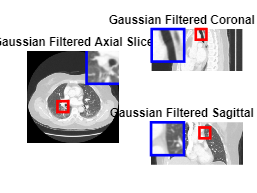

% FWHM
fwhm = 2 * sqrt(2 * log(2));
sigma_x = 2 / fwhm;
sigma_y = 2 / fwhm;
sigma_z = 1 / fwhm;
sigma_vox_x = sigma_x / pixelSpacing;
sigma_vox_y = sigma_y / pixelSpacing;
sigma_vox_z = sigma_z / sliceSpacing;

% Apply 3D Gaussian filter using imgaussfilt3
volume_gauss = imgaussfilt3(volume, [sigma_vox_x, sigma_vox_y, sigma_vox_z]);

figure, tiledlayout(2,2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile(1, [2 1]), display_magnified_roi(squeeze(volume_gauss(:,:,mid_z)), roi, magnification_factor, overlay_position, gca);
title("Gaussian Filtered Axial Slice");
nexttile, display_magnified_roi(squeeze(volume_gauss(:,mid_x,:)).', [250 1 roi_w roi_h], magnification_factor, [1 1], gca);
title("Gaussian Filtered Coronal Slice");
nexttile, display_magnified_roi(squeeze(volume_gauss(mid_y,:,:)).', [270 30 roi_w roi_h], magnification_factor, [1 1], gca);
title("Gaussian Filtered Sagittal Slice");
print('Gaussian Blurring', '-dsvg')

## IV. Foramina

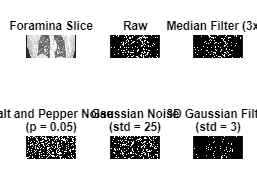

% Get foramina slice
foramina_slice = squeeze(volume(512-180,:,:)).';
figure, tiledlayout(2,3, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile, imshow(foramina_slice), title("Foramina Slice");

% Canny edge detection on raw slice
edges_raw = edge(foramina_slice, 'Canny');
nexttile, imshow(edges_raw), title("Raw");

% 3x3 median filter
foramina_median_filt = medfilt2(foramina_slice, [3 3]);
edges_median_filtered = edge(foramina_median_filt, 'Canny');
nexttile, imshow(edges_median_filtered), title("Median Filter (3x3)");

% Salt and Pepper Noise
foramina_salt_pepper = add_seasoning(foramina_slice, 0.05);
edges_salt_pepper = edge(foramina_salt_pepper, 'Canny');
nexttile, imshow(edges_salt_pepper), title({"Salt and Pepper Noise", "(p = 0.05)"});

% Gaussian Noise
foramina_gauss_noise = add_gauss_noise(foramina_slice, 25);
edges_gauss_noise = edge(foramina_gauss_noise, 'Canny');
nexttile, imshow(edges_gauss_noise), title({"Gaussian Noise", "(std = 25)"});

% 3D Gaussian filter
foramina_3D_gauss_filt = imgaussfilt3(foramina_slice, 3);
edges_3D_gauss = edge(foramina_3D_gauss_filt, 'Canny');
nexttile, imshow(edges_3D_gauss), title({"3D Gaussian Filter", "(std = 3)"});
print('Foramina', '-dsvg')

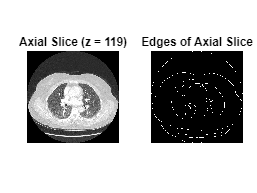


% Axial slice
axial_3D_gauss_filt = imgaussfilt3(axial_slice, 7);
edges_axial = edge(axial_3D_gauss_filt, 'Canny');
figure, tiledlayout('horizontal', "TileSpacing", "Compact", "Padding", "Compact");
nexttile, imshow(axial_slice), title("Axial Slice (z = 119)");
nexttile, imshow(axial_3D_gauss_filt), title("Gaussian Filter (std = 7)")
nexttile, imshow(edges_axial), title("Edges of Axial Slice");
print('Axial Edge', '-dsvg')